# Assignment 3

# Control Techniques beyound basic PID

## Problem1: LeadCompensator for Speed Improvement

Controlling plant

s = tf('s');
transfer_function = 1/((s+2)*(s+5)*s)


transfer_function =
 
          1
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.


PID Controller Designing 

% Using the builtin auto tuning in the PID controller
pidController = pidtune(transfer_function, 'PID')


pidController =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 35, Ki = 9.01, Kd = 20.1
 
Continuous-time PID controller in parallel form.


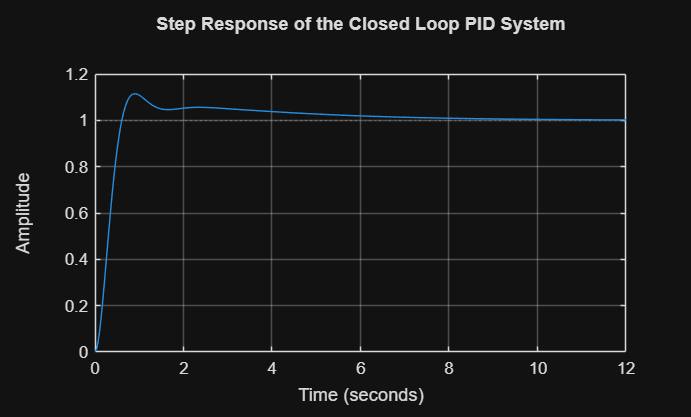

% Now generating the closed loop system 
pid_system = feedback(pidController*transfer_function,1);
% Step response of the closed loop system
step(pid_system);
title('Step Response of the Closed Loop PID System');
grid on

Info_PID = stepinfo(pid_system)

Info_PID = struct with fields:
         RiseTime: 0.4083
    TransientTime: 5.9509
     SettlingTime: 5.9509
      SettlingMin: 0.9285
      SettlingMax: 1.1154
        Overshoot: 11.5379
       Undershoot: 0
             Peak: 1.1154
         PeakTime: 0.9107


Risetime_PID = Info_PID.RiseTime;
Settlingtime_PID = Info_PID.SettlingTime;
Overshoot_PID = Info_PID.Overshoot;

Checking the final steady state value 

[y , t] = step(pid_system);
y_ss = y(end);
e_ss = 1-y_ss 

e_ss = -0.0046

Observations :

- Using the in built pid tuner makes the system good enough but still there exsists an error . The error is about to zero but not exactly zero which shows that the work of the pidtune is not minimising the steady state error but it gives overall increment in the performance of the plant .

- Overshoot more then 10.

- Very unstable system.

Tryng mannual tuning :

Exaple system is unstable for DC Motor.

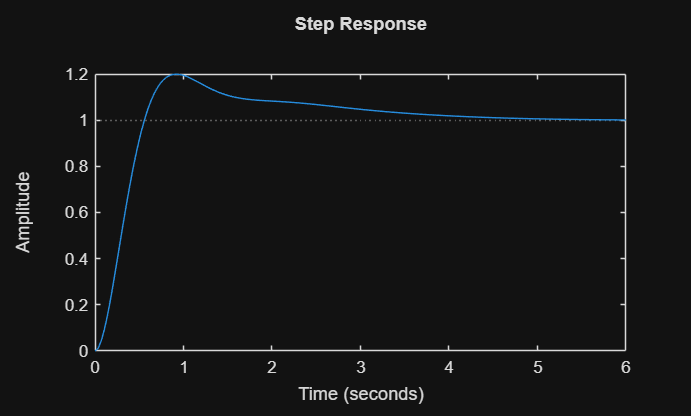

pidController2 = pid(40,20,20);
pid_system2 = feedback(pidController2*transfer_function,1);
step(pid_system2)

stepinfo(pid_system2)

ans = struct with fields:
         RiseTime: 0.3808
    TransientTime: 3.9390
     SettlingTime: 3.9390
      SettlingMin: 0.9016
      SettlingMax: 1.1992
        Overshoot: 19.9235
       Undershoot: 0
             Peak: 1.1992
         PeakTime: 0.9128


Unable to find the value at which the steady state error is exaclty zero and the best value is found by the tuner as above it overshoot incresed a lot which is very harmful for a DC motor. 

Lead compensator designing 

A lead compensator increses the phase of the plant by some value .

For this the zero of the compensator should always be closer to origin then the pole .

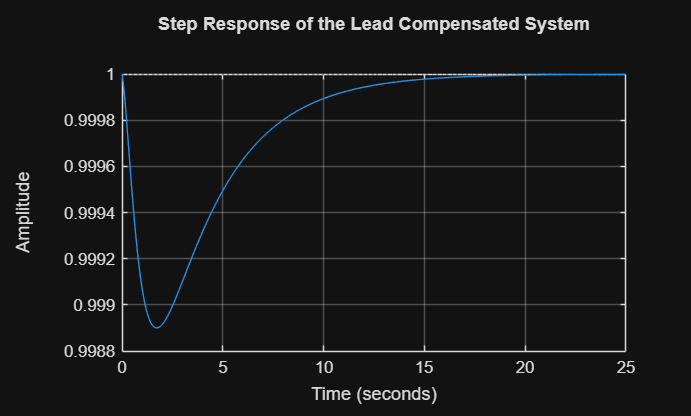

% Equation of the compensator :
%given
z=3;
p=15;
Kc = 100;
lead_compensator = (Kc*(s+z))/(s+p);
% Compensator = lead_comprnsator * Gain * Transfer_function
G_comp = lead_compensator*pidController;
% Simulate the step response of the compensated system
lead_compensated_system = feedback(G_comp, 1);
step(lead_compensated_system);
title('Step Response of the Lead Compensated System');
grid on;


% Extracting Rise time ,Settling time and Overshoot 
Info_lead = stepinfo(lead_compensated_system)

Info_lead = struct with fields:
         RiseTime: 0
    TransientTime: 15.0262
     SettlingTime: 0
      SettlingMin: 0.9989
      SettlingMax: 1
        Overshoot: 0
       Undershoot: 0
             Peak: 1
         PeakTime: 0


Risetime_lead = Info_lead.RiseTime;
settlingtime_lead = Info_lead.SettlingTime;
Overshoot_lead = Info_lead.Overshoot;

Checking the final steady state value 

[y , t] = step(lead_compensated_system);
y_ss = y(end);
e_ss = 1-y_ss %% Nearly zero but not exactly 

e_ss = 1.4671e-06

I checked all the different possible values of the Kc and these are my observations :

- Kc = 0.1(very small): Very high rise ,settling time ,overshoot zero but steady state error exsists , no ossilations .

- Kc = 1 : Rise =0 and settling time improved very much but still more scope of improvement .

- Kc =5 : Minima value decresing but still more improvement .

- Kc= 6-10 : Decrese continous to 0.99 and also the overshoot =0.

- Kc =15:20 : decrement with overshoot zero.

- Kc increse cause increse in accuracy value of Kc can be decided by the use case of the motor.

Best value is 45(approx)

Analysis of the PID system and Lead compensator :

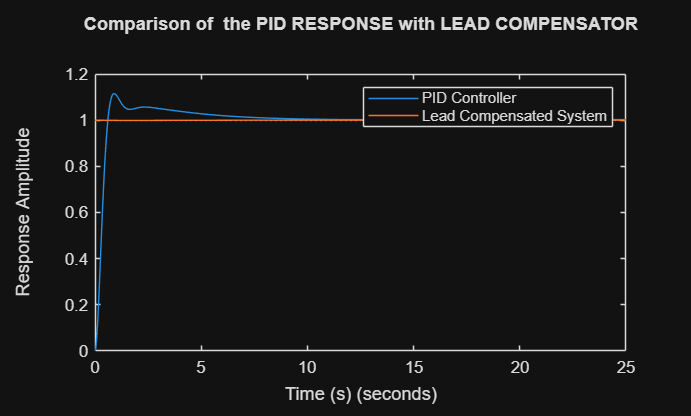

% Plotting both the responses for the comparisons 
step(pid_system)
hold on
step(lead_compensated_system)
legend('PID Controller', 'Lead Compensated System');
xlabel('Time (s)');
ylabel('Response Amplitude');
title("Comparison of  the PID RESPONSE with LEAD COMPENSATOR")
hold off

Analysis by the values of rise time ,overshoot and settling time 

Tabled Comparison of the data of step informations 

Comparison_table = table( ...
    [Risetime_lead;Risetime_PID], ...
    [settlingtime_lead;Settlingtime_PID], ...
    [Overshoot_lead;Overshoot_PID], ...
    'VariableNames',{'Rise Time' , 'Settling Time' ,'Overshoot' },'RowNames',{'lead_compensated_system','pid_system'})

Comparison_table = 2×3 table
                               Rise Time    Settling Time    Overshoot
                               _________    _____________    _________

    lead_compensated_system           0             0              0  
    pid_system                  0.40833        5.9509         11.538  


• Explain how the lead compensator improved the transient response?

That extra phase increases the phase margin, which typically increases the damping ratio of the dominant poles, reducing overshoot and oscillations in the step response.

PARAMETER EXPERIMENTATION:

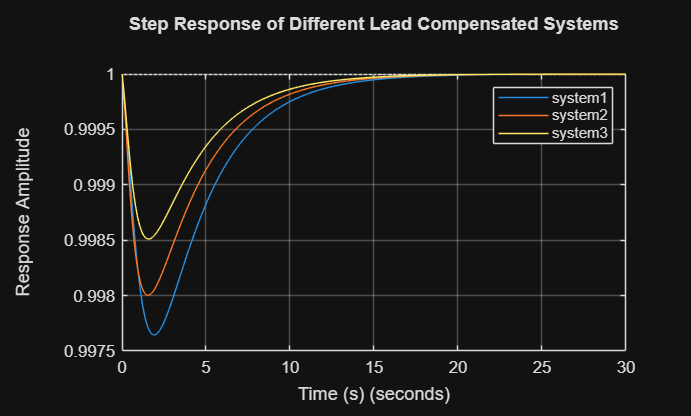

% Equation of the compensator :
%given
z1=2;,z2=5;,z3=4;
p1=10;,p2=20;,p3=12;
Kc = 45;
lead_compensator1 = (Kc*(s+z1))/(s+p1);
lead_compensator2 = (Kc*(s+z2))/(s+p2);
lead_compensator3 = (Kc*(s+z3))/(s+p3);
G_comp1 = lead_compensator1*pidController;
G_comp2 = lead_compensator2*pidController;
G_comp3 = lead_compensator3*pidController;
% Simulate the step response of the compensated system
lead_compensated_system1 = feedback(G_comp1, 1);
lead_compensated_system2 = feedback(G_comp2, 1);
lead_compensated_system3 = feedback(G_comp3, 1);

step(lead_compensated_system1);
hold on
step(lead_compensated_system2);
step(lead_compensated_system3);
title('Step Response of Different Lead Compensated Systems');
grid on;
xlabel('Time (s)');
ylabel('Response Amplitude');
legend('system1','system2','system3')
hold off

        Discussion:

- Different values of the poles and gains make different minima in the graph of the output for the first system the Ratio of pole and zero is 5 and 4 , 3 for the other two .This high ratio leads to high minima of the step response .

- also the minima is shifting backward .

### Problem2: LagCompensatorfor Steady-State Accuracy

Plant 

transfer_function_2 = 50/((s+1)*(s+3)*(s+8))


transfer_function_2 =
 
             50
  ------------------------
  s^3 + 12 s^2 + 35 s + 24
 
Continuous-time transfer function.


P Controller Designing 

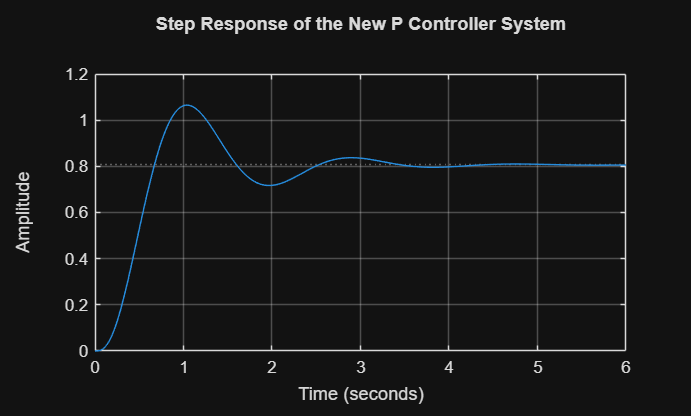

Kp = 2;                               %Given 
pid_controller_2 = pid(Kp, 0, 0); % Define the P controller with proportional gain Kp
pid_system_2 = feedback(pid_controller_2 * transfer_function_2, 1); % Closed-loop system with new transfer function
step(pid_system_2); % Step response of the new P controller system
grid on; % Enable grid for better visualization
title('Step Response of the New P Controller System'); % Title for the plot



%finding the error at stedy state 
[y_P,t_p] = step(pid_system_2);
y_ss_P = y_P(end);
e_ss_P = 1-y_ss_P

e_ss_P = 0.1920

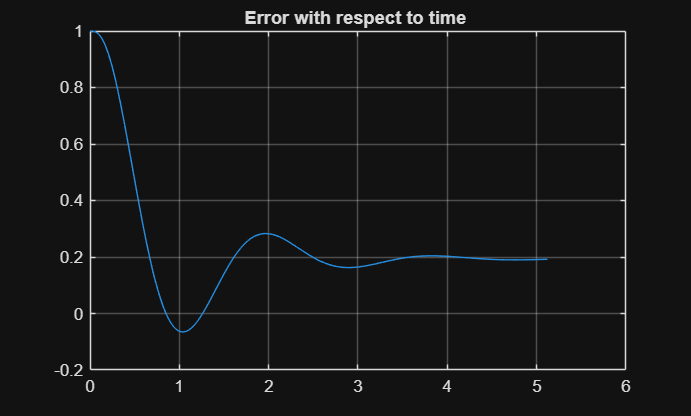


% Plotting error with respect to time 
e_P = 1-y_P;
plot(t_p,e_P)
grid on
title("Error with respect to time ")

The only P - controller is showing large steady state error .

Lag compensator design + P- controller  

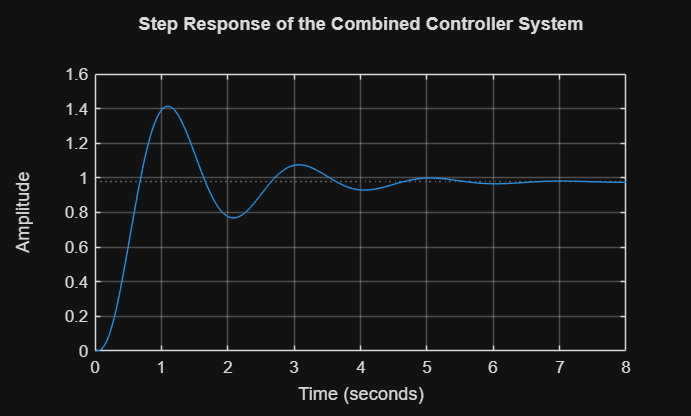

Kc = 1;
z = 1;
p = 0.1;
C_lag = (Kc*(s+z))/(s+p);
C_combine = Kp*C_lag;
% Simulate the step response of the combined controller system
combined_system = feedback(C_combine * transfer_function_2, 1);
step(combined_system);
title('Step Response of the Combined Controller System');
grid on;

Steady State error reductions 

[y_lag, t_lag] = step(combined_system);
y_ss_lag = y_lag(end);
e_ss_lag = 1-y_ss_lag

e_ss_lag = 0.0254

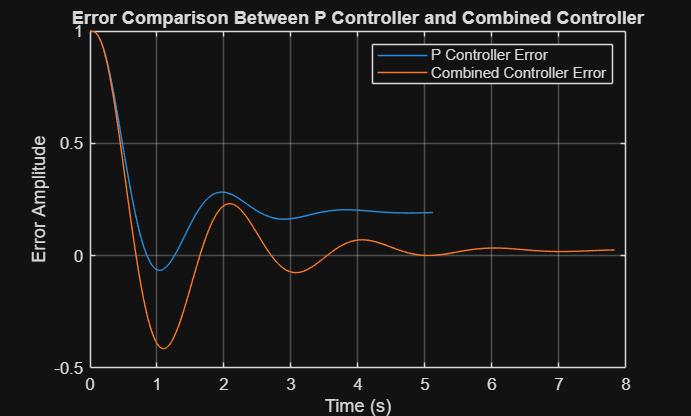

e_lag = 1-y_lag;
plot(t_p,e_P)
hold on 
plot(t_lag,e_lag)
grid on ;
% Plotting the error for both systems
xlabel('Time (s)');
ylabel('Error Amplitude');
legend('P Controller Error', 'Combined Controller Error');
title('Error Comparison Between P Controller and Combined Controller');
hold off;

Table of comparisons for errors and settling times 

Error_percent_ss = ((e_ss_P - e_ss_lag)*100)/e_ss_P;
info_P = stepinfo(pid_system_2);
info_lag = stepinfo(combined_system);
ST_P = info_P.SettlingTime;
ST_lag = info_lag.SettlingTime;

Comaprison = table([e_ss_P;e_ss_lag], ...
    [ST_P;ST_lag], ...
    [Error_percent_ss;Error_percent_ss], ...
    'VariableNames',{'Steady State Error','Settling Time','Error percentage'}, ...
    'RowNames',{'P-controller','Lag Compensator'})

Comaprison = 2×3 table
                       Steady State Error    Settling Time    Error percentage
                       __________________    _____________    ________________

    P-controller             0.19202            3.2198             86.778     
    Lag Compensator         0.025389            5.2126             86.778     


Observations :

- Settling time incresed by a significant amount .

- The response became slower then the P-controller .

Changing pole to 0.01

Kc = 1;
z = 1;
p = 0.01;
C_lag2 = (Kc*(s+z))/(s+p);
C_combine2 = Kp*C_lag;
% Simulate the step response of the combined controller system
combined_system2 = feedback(C_combine2 * transfer_function_2, 1);
step(combined_system2);
title('Step Response of the Combined Controller System');
grid on;


%%%% ERROR OF THE SYSTEM 
[y_lag2, t_lag2] = step(combined_system2);
y_ss_lag2 = y_lag2(end);
e_ss_lag2 = 1-y_ss_lag2

e_ss_lag2 = 0.0254

TRADE OFF ANALYSIS OF THE SYSTEMS :

- The accuracy increased very much.

- Response of the Lag compensator is slower then the only P-controller.

### Problem 3: Feedforward + Feedback Control

new plant : cruise control system

G = 1/(s+0.5)                          %Plant 


G =
 
     1
  -------
  s + 0.5
 
Continuous-time transfer function.


Feedback only Plant 

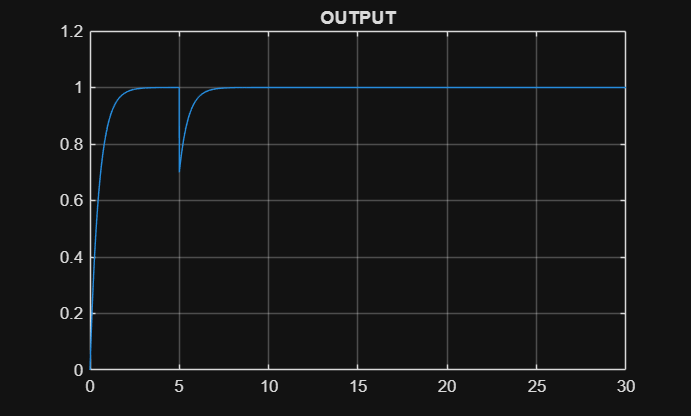

% Feedback-Only Control Implementation
% Time vector 
dt = 0.01;
t = 0:dt:30;
r = ones(size(t)); % Reference speed 

% Disturbances
d_pred = 0.3 * (t >= 5);       % Disturbance signals 

% PI Controller Parameters 
Kp = 2; Ki = 1;
e_int_fb = 0; 
y_fb = zeros(size(t));
u_fb_log = zeros(size(t));

% Discrete Plant Simulation (y = G(u) - d)
G = tf(1, [1 0.5]); 
sys_d = c2d(G, dt); 
[A, B, C, D] = ssdata(sys_d);
x_fb = 0;

for i = 2:length(t)
    % Error calculation 
    e_fb = r(i) - y_fb(i-1);
    
    % PI Control law 
    u_fb = Kp*e_fb + Ki*e_int_fb;
    e_int_fb = e_int_fb + e_fb*dt;
    
    % Plant Update with disturbance
    x_fb = A*x_fb + B*u_fb;
    y_fb(i) = C*x_fb - d_pred(i); 
    u_fb_log(i) = u_fb;
end
error_fb = r - y_fb;

plot(t,y_fb)
grid on
title(" OUTPUT ")

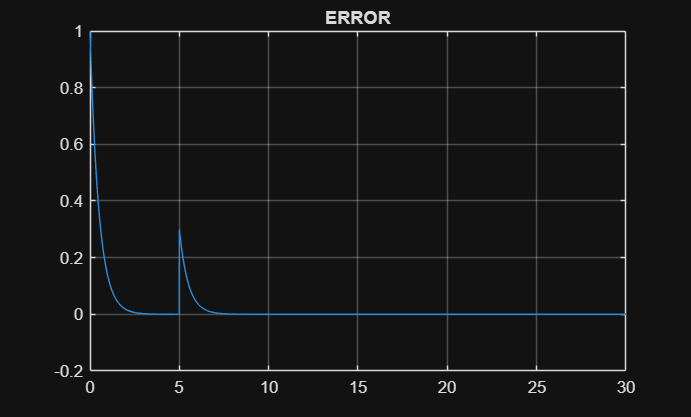

plot(t,error_fb)
grid on 
title(" ERROR ")

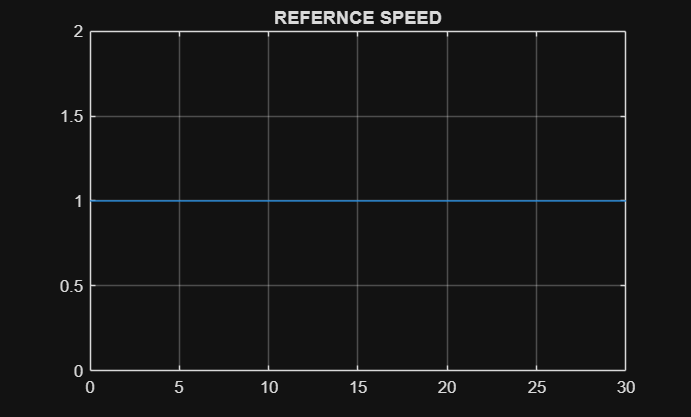

plot(t,r)
grid on 
title(" REFERNCE SPEED ")

- The PI controller eventually eliminates steady-state error due to the integral term .

- However, when the disturbance hits at t=5, the speed drops significantly because the controller only reacts *after* the error is detected

Feedback + Feedforward Control System

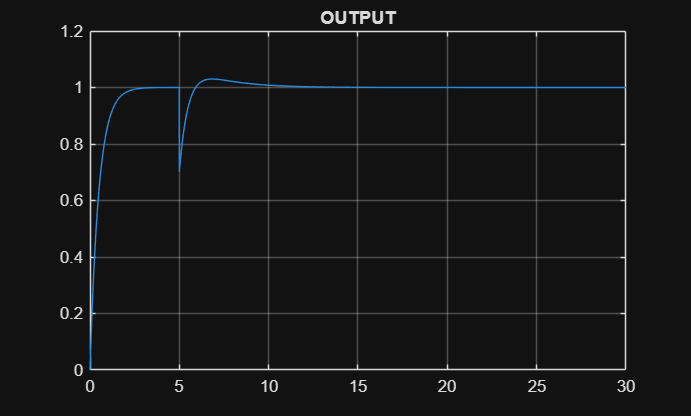

Kff = 1 / dcgain(G); 

y_ff = zeros(size(t));
x_ff = 0;
e_int_ff = 0;

for i = 2:length(t)
    % Feedback portion
    e_ff = r(i) - y_ff(i-1);
    u_fb_part = Kp*e_ff + Ki*e_int_ff;
    e_int_ff = e_int_ff + e_ff*dt;
    
    % Feedforward portion (only for predicted disturbance) [cite: 106, 139]
    if t(i) >= 5
        u_ff_part = Kff * 0.3; % Compensate for known disturbance
    else
        u_ff_part = 0;
    end
    
    % Total Control Signal
    u_total = u_fb_part + u_ff_part;
    
    % Plant Update
    x_ff = A*x_ff + B*u_total;
    y_ff(i) = C*x_ff - d_pred(i);
end

error_ff = r - y_ff;

plot(t,y_ff)
grid on
title(" OUTPUT ")

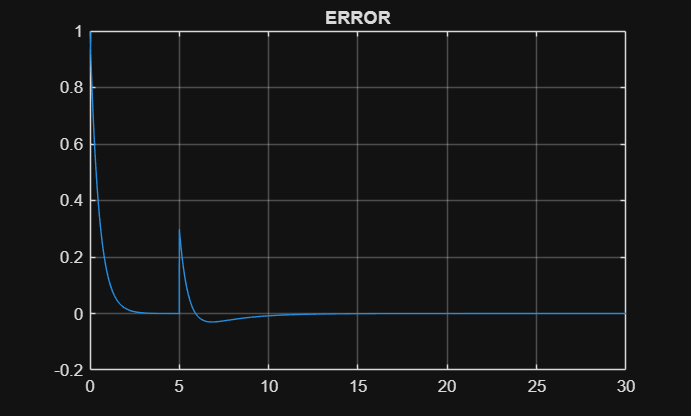

plot(t,error_ff)
grid on 
title(" ERROR ")

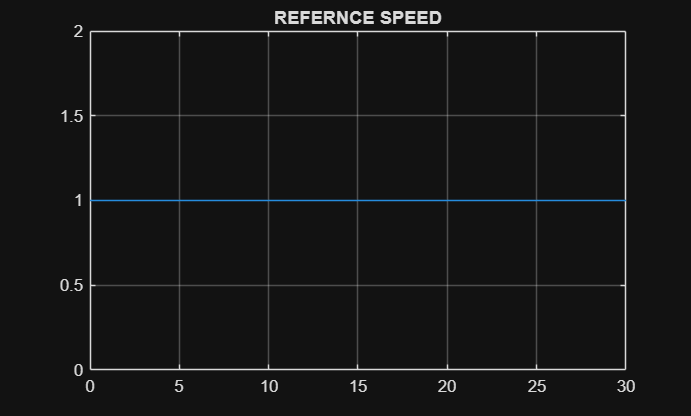

plot(t,r)
grid on 
title(" REFERNCE SPEED ")

Comparisons Plots 

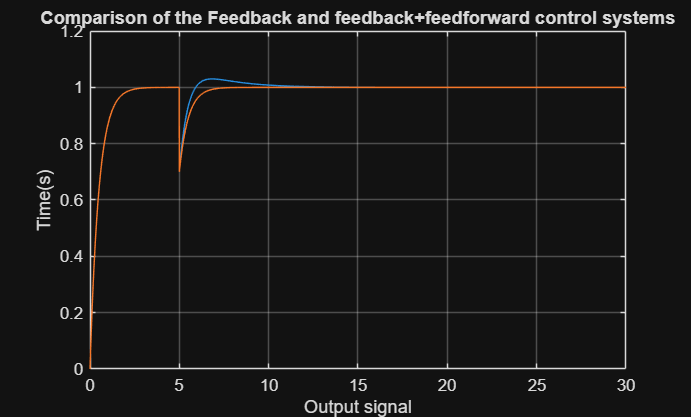

%Generating comarison plots 
plot(t,y_ff)
hold on 
plot(t,y_fb)
grid on 
title(" Comparison of the Feedback and feedback+feedforward control systems ")
xlabel("Output signal")
ylabel("Time(s)")
hold off

Explain why feedforward helps with disturbance rejection?

- feedforward system waits for error to appear and reacts when error start affecting the output.

- The feedforward system uses the measured or known disturbance and compensates for it in advance .

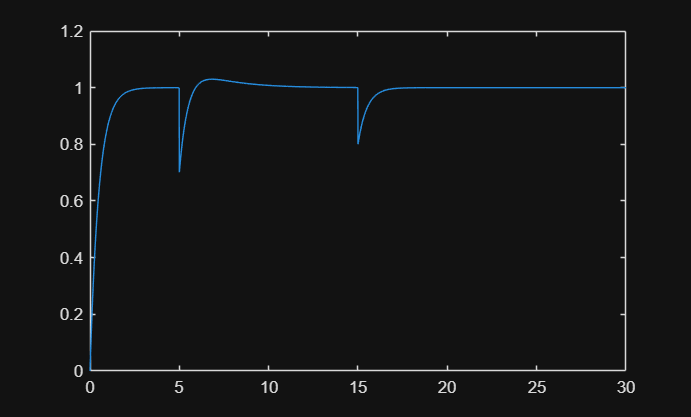

d_pred = 0.3 * (t >= 5);    
d_unpred = 0.2 * (t >= 15);    
d_total = d_pred + d_unpred;

Kff = 1 / dcgain(G); 

y_ff = zeros(size(t));
x_ff = 0;
e_int_ff = 0;

for i = 2:length(t)
    % Feedback portion
    e_ff = r(i) - y_ff(i-1);
    u_fb_part = Kp*e_ff + Ki*e_int_ff;
    e_int_ff = e_int_ff + e_ff*dt;
    
    % Feedforward portion (only for predicted disturbance) [cite: 106, 139]
    if t(i) >= 5
        u_ff_part = Kff * 0.3; 
    else
        u_ff_part = 0;
    end
    
    % Total Control Signal
    u_total = u_fb_part + u_ff_part;
    
    % Plant
    x_ff = A*x_ff + B*u_total;
    y_ff(i) = C*x_ff - d_total(i);
end

plot(t,y_ff)

### Problem 4: Simple MIMO System Control

making MIMO Transfer Function

G11 = 2/(s+1);
G12 = 0.2/(s+2);
G21 = 1/(s+1.5);
G22 = 3/(s+1);

G = [G11 G12;G21 G22]


G =
 
  From input 1 to output...
         2
   1:  -----
       s + 1
 
          1
   2:  -------
       s + 1.5
 
  From input 2 to output...
        0.2
   1:  -----
       s + 2
 
         3
   2:  -----
       s + 1
 
Continuous-time transfer function.



U1 = 1;
U2 = 0;
U = [U1 ;U2]

U =      1
     0


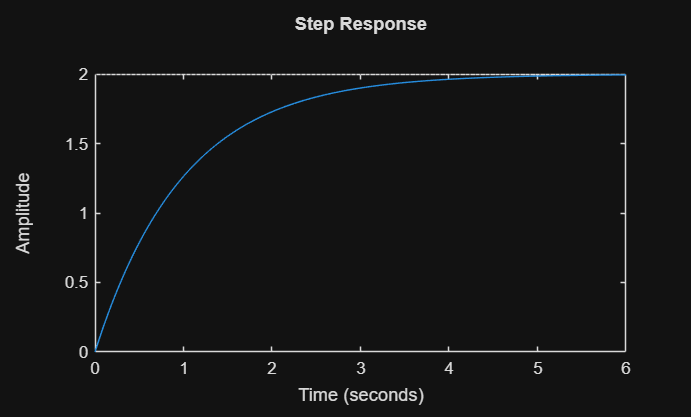


H1 = G11 * U1 + G12 * U2;
H2 = G21 * U1 + G22 * U2;

step(H1)

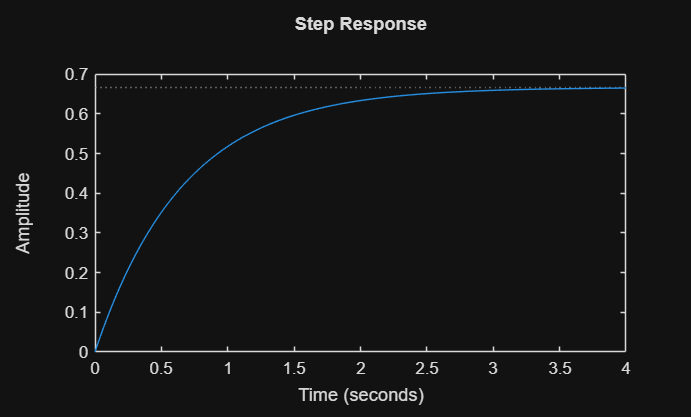

step(H2)


U1 = 0;
U2 = 1;
U = [U1 ;U2]

U =      0
     1


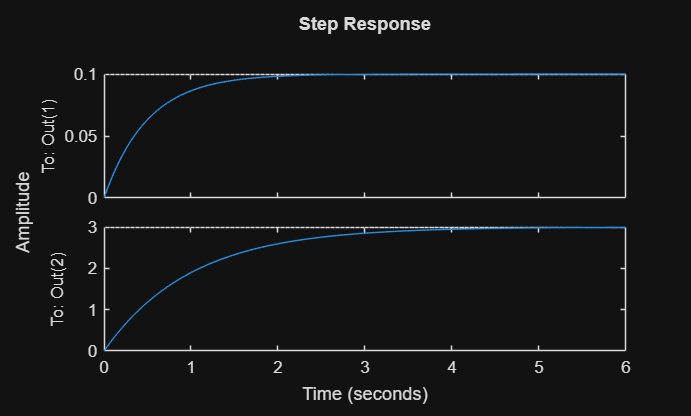


step(G*U)

Decentralized PI Controller 

Above we have discovered the Open loop system and now closed loop system

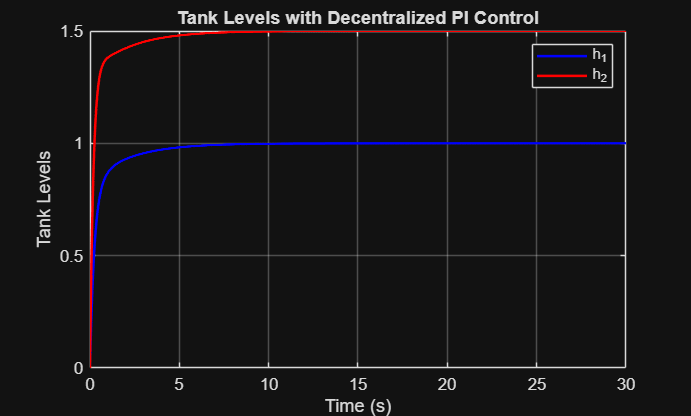

Kp1 = 1.5;
Ki1 = 0.8;
Kp2 = 1.2;
Ki2 = 0.6;

C1 = pid(Kp1,Ki1,0);
C2 = pid(Kp2,Ki2,0);

r1 = 1*ones(size(t));
r2 = 1.5*ones(size(t));
r = [r1, r2];

h1 = zeros(size(t));
h2 = zeros(size(t));
u1 = zeros(size(t));
u2 = zeros(size(t));
e1_int = 0;
e2_int = 0; 

sys_d = c2d(G, dt);
[A, B, C, D] = ssdata(sys_d);
x = zeros(size(A,1), 1);

for i = 2:length(t)
    % Calculate the reference signals for the tanks
    e1 = r1(i) - h1(i-1);
    e2 = r2(i) - h2(i-1);
    
    % Update integral errors
    e1_int = e1_int + e1 * dt;
    e2_int = e2_int + e2 * dt;
    
    % Control signals for each tank
    u1(i) = Kp1 * e1 + Ki1 * e1_int;
    u2(i) = Kp2 * e2 + Ki2 * e2_int;

    u_vec = [u1(i); u2(i)];
    x = A*x + B*u_vec;
    y = C*x + D*u_vec;

    h1(i) = y(1); % Update tank level for tank 1 
    h2(i) = y(2); % Update tank level for tank 2

end 

%% Plot tank levels
figure;
plot(t, h1, 'b', t, h2, 'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('Tank Levels')
legend('h_1','h_2')
title('Tank Levels with Decentralized PI Control')
grid on

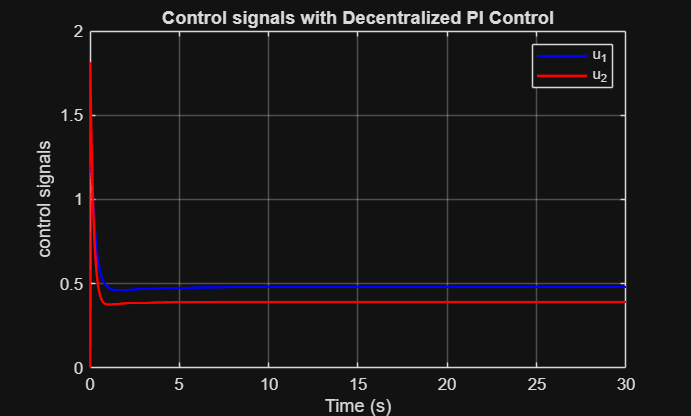


figure;
plot(t, u1, 'b', t, u2, 'r','LineWidth',1.5)
xlabel('Time (s)')
ylabel('control signals')
legend('u_1','u_2')
title('Control signals with Decentralized PI Control')
grid on

Analysis :

- yes the change in h1 will affect the h2 :

H1 = G11 * U1 + G12 * U2;
H2 = G21 * U1 + G22 * U2;

as there is any change in h1 will definitely cause a change in the h2 .

2. yes 

3.Typically, the interaction between the two PI loops causes more oscillation and overshoot than if the tanks were independent.

## Summary Questions 

- lead compensator is used when the system is sluggish and and need faster response and it decreses the overshoot with increase in stability matgins .higer gains cause actuator saturations and and can cause osscilations .

- Advantages(as observed from the table ): increse in steady state accuracy ,as steady state error value becomes very less and it is mainly useful when accuray matters more then the steady state time .Disadvantages : The settling time is incresed means system becomes slow,Spike in number of ossilations can also be observed .

- It is called proactive as it does act before the error appears.

- The rise in number of inputs and outputs is itself a very big issue , As the inputs and outputs are linked to one another so this causes coupling effect,much larger number of poles and zeros are interacting this cause hard to  analyse the system.